# Random graph simulation for various values of alpha - giant component size

Clear Workspace

clear

Define parameters, initiate random number generator

gSize = 1000;
trials = 100;
alpha = [0.1 0.2 0.3 0.5 0.7 0.8 0.9 1 1.1 1.2 1.3 1.5 2 3 5 7 10 20 50 70 100]

alpha =     0.1000    0.2000    0.3000    0.5000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.5000    2.0000    3.0000    5.0000    7.0000   10.0000   20.0000   50.0000   70.0000  100.0000


rng shuffle;


Initiate matrices and tables

A = zeros(gSize);      % initiate adjacency matrix
gcSize = zeros(length(alpha), trials);     % inititate giant component matrix
subgNumber = zeros(length(alpha), trials);   
gAlpha = zeros(length(alpha),1);
gcAvgSize = zeros(length(alpha),1);
gcMaxSize = zeros(length(alpha),1);
gcMinSize = zeros(length(alpha),1);
subgAvgNumber = zeros(length(alpha),1);
subgMaxNumber = zeros(length(alpha),1);
subgMinNumber = zeros(length(alpha),1);
gcSizeStats = table(gAlpha, gcAvgSize, gcMaxSize, gcMinSize, subgAvgNumber, subgMaxNumber, subgMinNumber);
gcSizeStats.gAlpha = (alpha)';


### For all values of alpha 

for k = 1:length(alpha)
    fprintf("alpha = %d\n",alpha(k))
    for i = 1:trials

Create adjacency matrix

        r = rand(gSize) < alpha(k)/gSize;
        A = triu(r,1);
        A = A + A';

Calculate  graph and giant component

        names = string(1:gSize);
        G = graph(A,names,"omitselfloops","upper");
        [bin,binsize] = conncomp(G);
        % binsize
        gcSize(k,i) = max(binsize);
        subgNumber(k,i) = length(binsize);
        fprintf('%d',mod(i,10))
    end         
    gcSizeStats.gcAvgSize(k) = mean(gcSize(k,:));
    gcSizeStats.gcMaxSize(k) = max(gcSize(k,:));
    gcSizeStats.gcMinSize(k) = min(gcSize(k,:));
    gcSizeStats.subgAvgNumber(k) = mean(subgNumber(k,:));
    gcSizeStats.subgMaxNumber(k) = max(subgNumber(k,:));
    gcSizeStats.subgMinNumber(k) = min(subgNumber(k,:));
end

alpha = 1.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 2.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 3.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 5.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 7.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 8.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 9.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.100000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.200000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.300000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.500000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 2


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 3


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 5


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 7


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 10


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 20


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 50


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 70


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 100


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

### Plot statistics and errorbar diagram of giant component size

gcSizeStats

gcSizeStats = 21×7 table
    gAlpha    gcAvgSize    gcMaxSize    gcMinSize    subgAvgNumber    subgMaxNumber    subgMinNumber
    ______    _________    _________    _________    _____________    _____________    _____________

     0.1         3.52           6            2          950.54             971              934     
     0.2          4.8           9            3          900.31             921              871     
     0.3         6.62          12            4           850.2             882              823     
     0.5        10.83          20            7          748.54             780              710     
     0.7        22.53          56           11          646.58             683              599     
     0.8        30.33        

errorbar(gcSizeStats.gAlpha, ...
    gcSizeStats.gcAvgSize, ...
    gcSizeStats.gcAvgSize - gcSizeStats.gcMinSize, ...
    gcSizeStats.gcMaxSize - gcSizeStats.gcAvgSize, "-ro")
hold on;
errorbar(gcSizeStats.gAlpha, ...
    gcSizeStats.subgAvgNumber, ...
    gcSizeStats.subgAvgNumber - gcSizeStats.subgMinNumber, ...
    gcSizeStats.subgMaxNumber - gcSizeStats.subgAvgNumber, "-bo")
title("Giant component size and number of subgraphs","n=1000 / 100 trials")
legend("Size of giant component","Number of subgraphs")
xlabel("Alpha")
ylabel("Count")
hold off;
set(gca,'XScale','log');


save plot and data

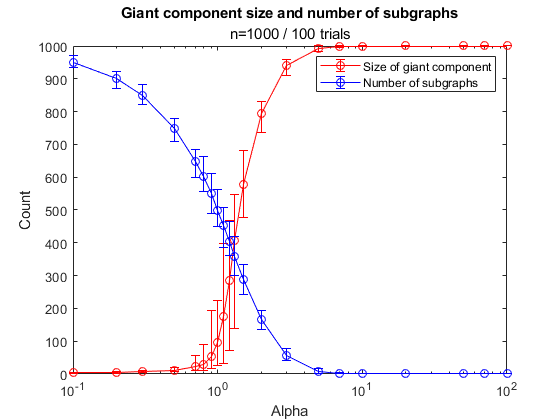

writetable(gcSizeStats,'giant_component_Stats.xlsx');  
print("giant_component.png",'-dpng');